%======== using Lalanne RotorDynamic Book finite element analysis - Direct Methode ========

n = 3;                   % Number of toltal Nodes
L_tot = 5; % [m]         % Total length of shaft
L = L_tot/n;             % Length Of each node
r_s = 0.1;               % shaft radius
rho_s = 7800;            % shaft density
E = 2e11;                % Young Modules

omega = 1;

pi = 3.1415

pi = 3.1415

S = pi*r_s^2             % Shaft Cross section Area

S = 0.0314

I = pi*r_s^4/4

I = 7.8538e-05


M_ref = [156    0     0     -22*L   54    0     0      13*L;
         0      156   22*L   0      0     54   -13*L   0;
         0      22*L  4*L^2  0      0     13*L -3*L^2  0;
        -22*L   0     0      4*L^2 -13*L  0     0     -3*L^2;
         54     0     0     -13*L   156   0     0      22*L;
         0      54    13*L   0      0     156  -22*L   0;
         0     -13*L -3*L^2  0      0    -22*L  4*L^2  0;
         13*L   0     0     -3*L^2  22*L  0     0      4*L^2]*rho_s*S*L/420

M_ref =   151.6896         0         0  -35.6535   52.5079         0         0   21.0680
         0  151.6896   35.6535         0         0   52.5079  -21.0680         0
         0   35.6535   10.8041         0         0   21.0680   -8.1031         0
  -35.6535         0         0   10.8041  -21.0680         0         0   -8.1031
   52.5079         0         0  -21.0680  151.6896         0         0   35.6535
         0   52.5079   21.0680         0         0  151.6896  -35.6535         0
         0  -21.0680   -8.1031         0         0  -35.6535   10.8041         0
   21.0680         0         0   -8.1031   35.6535         0         0   10.8041



M_s = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*rho_s*I/(30*L)

M_s =     0.4411         0         0   -0.0613   -0.4411         0         0   -0.0613
         0    0.4411    0.0613         0         0   -0.4411    0.0613         0
         0    0.0613    0.1361         0         0   -0.0613   -0.0340         0
   -0.0613         0         0    0.1361    0.0613         0         0   -0.0340
   -0.4411         0         0    0.0613    0.4411         0         0    0.0613
         0   -0.4411   -0.0613         0         0    0.4411   -0.0613         0
         0    0.0613   -0.0340         0         0   -0.0613    0.1361         0
   -0.0613         0         0   -0.0340    0.0613         0         0    0.1361


     
M = zeros(n*4);

for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              M(1+k*4+i,1+k*4+j) = M(1+k*4+i,1+k*4+j) + M_ref(1+i,1+j) + M_s(1+i,1+j);
            end
        end
    end
end


D_d = 1;                                   % Disk Diameter
r_d = D_d/2;                               % Disk Radius
b_d = 0.5;                                 % Disk Width
rho_d = 7850;                              % Disk Density
V_d = b_d*pi*D_d^2/4;                      % Disk Volume
M_D = rho_d*V_d;                           % Disk Mass
I_Dx = 0.25*M_D*r_d^2  +  (1/12)*M_D*b_d;  % Disk Inertia

n_d = 2;                                   % Number Of Node(s) Which Disk is Located
M_disk = [M_D;M_D;I_Dx;I_Dx].*eye(4);      % Disk Mass Matrix

k = n_d - 1

k = 1

if 1+k*4 < n*4
    for i = 0:3
        for j = 0:3
            M(1+k*4+i,1+k*4+j)= M(1+k*4+i,1+k*4+j) + M_disk(1+i,1+j);
        end
    end
end
 
      
C_ref = [0   -36  -3*L    0      0    36     -3*L    0;
         36   0    0     -3*L   -36   0       0     -3*L;
         3*L  0    0     -4*L^2 -3*L  0       0      L^2;
         0    3*L  4*L^2  0      0   -3*L    -L^2    0;
         0    36   3*L    0      0   -36      3*L    0;
        -36   0    0      3*L    36   0       0      3*L;
         3*L  0    0      L^2   -3*L  0       0     -4*L^2;
         0    3*L -L^2    0      0   -3*L     4*L^2  0]*(rho_s*I*omega/(15*L))

C_ref =          0   -0.8821   -0.1225         0         0    0.8821   -0.1225         0
    0.8821         0         0   -0.1225   -0.8821         0         0   -0.1225
    0.1225         0         0   -0.2723   -0.1225         0         0    0.0681
         0    0.1225    0.2723         0         0   -0.1225   -0.0681         0
         0    0.8821    0.1225         0         0   -0.8821    0.1225         0
   -0.8821         0         0    0.1225    0.8821         0         0    0.1225
    0.1225         0         0    0.0681   -0.1225         0         0   -0.2723
         0    0.1225   -0.0681         0         0   -0.1225    0.2723         0


  
C = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              C(1+k*4+i,1+k*4+j)=C(1+k*4+i,1+k*4+j)+C_ref(1+i,1+j);
            end
        end
    end
end      
      
a = 0;
K_C = [12   0    0        -6*L      -12     0     0        -6*L;
       0    12   6*L       0         0     -12    6*L       0;
       0    6*L (4+a)*L^2  0         0     -6*L  (2-a)*L^2  0;
      -6*L  0    0        (4+a)*L^2  6*L    0     0        (2-a)*L^2;
      -12   0    0         6*L       12     0     0         6*L;
       0   -12  -6*L       0         0      12   -6*L       0;
       0    6*L (2-a)*L^2  0         0     -6*L  (4+a)*L^2  0;
      -6*L  0    0        (2-a)*L^2  6*L    0     0        (4+a)*L^2;]*E*I/((1+a)*L^3)

K_C = 	1.0e+07 *

    4.0714         0         0   -3.3928   -4.0714         0         0   -3.3928
         0    4.0714    3.3928         0         0   -4.0714    3.3928         0
         0    3.3928    3.7698         0         0   -3.3928    1.8849         0
   -3.3928         0         0    3.7698    3.3928         0         0    1.8849
   -4.0714         0         0    3.3928    4.0714         0         0    3.3928
         0   -4.0714   -3.3928         0         0    4.0714   -3.3928         0
         0    3.3928    1.8849         0         0   -3.3928    3.7698         0
   -3.3928         0         0    1.8849    3.3928         0         0    3.7698


  
F = 1;      
K_F = [36   0    0     -3*L   -36   0       0     -3*L;
       0    36   3*L    0      0   -36      3*L    0;
       0    3*L  4*L^2  0      0   -3*L    -L^2    0;
      -3*L  0    0      4*L^2  3*L  0       0     -L^2;
      -36   0    0      3*L    36   0       0      3*L;
       0   -36  -3*L    0      0    36     -3*L    0;
       0    3*L -L^2    0      0   -3*L     4*L^2  0;
      -3*L  0    0     -L^2    3*L  0       0      4*L^2;]*F/(30*L)

K_F =     0.7200         0         0   -0.1000   -0.7200         0         0   -0.1000
         0    0.7200    0.1000         0         0   -0.7200    0.1000         0
         0    0.1000    0.2222         0         0   -0.1000   -0.0556         0
   -0.1000         0         0    0.2222    0.1000         0         0   -0.0556
   -0.7200         0         0    0.1000    0.7200         0         0    0.1000
         0   -0.7200   -0.1000         0         0    0.7200   -0.1000         0
         0    0.1000   -0.0556         0         0   -0.1000    0.2222         0
   -0.1000         0         0   -0.0556    0.1000         0         0    0.2222



K = zeros(n*4);
for k = 0:n
    if 1+k*4 < n*4 - n
        for i = 0:7
            for j = 0:7
              K(1+k*4+i,1+k*4+j)=K(1+k*4+i,1+k*4+j)+K_C(1+i,1+j)+K_F(1+i,1+j);
            end
        end
    end
end


landa=inv(M)*K;
[Eivec,Eival] = eig(landa)

Eivec =    -0.1478    0.1489   -0.0941   -0.0878   -0.3235   -0.2326    0.3557    0.4740    0.5319   -0.0319   -0.5598    0.1160
   -0.0000   -0.0000   -0.1153    0.1188    0.2712   -0.3523    0.3848   -0.2235   -0.2245   -0.5765    0.1063    0.5579
    0.0000    0.0000    0.5355   -0.5559   -0.3248    0.4220   -0.3478    0.2019   -0.0000    0.0000   -0.0638   -0.3347
   -0.6914    0.6912   -0.4371   -0.4110   -0.3875   -0.2786    0.3215    0.4284    0.0000    0.0000   -0.3359    0.0696
    0.0000    0.0050   -0.0032    0.0000   -0.0000    0.0000   -0.0312   -0.0415    0.5319   -0.0319    0.0000    0.0000
   -0.0000   -0.0000   -0.0039    0.0000   -0.0000    0.0000   -0.0337    0.0196   -0.2245   -0.5765    0.0000    0.0000
    0.0000    0.0000   -0.0000   -0.0159    0.2336   -0.3035    0.0000    0.0000   -0.0000    0.0000   -0.0638   -0.3347
   -0.0198    0.0000   -0.0000   -0.0118    0.2787    0.2004   -0.0000    0.0000    0.0000    0.0000   -0.3359    0.0696
    0.1478    0.1489   -

Eival = 	1.0e+07 *

    1.0079         0         0         0         0         0         0         0         0         0         0         0
         0    0.9898         0         0         0         0         0         0         0         0         0         0
         0         0    0.9898         0         0         0         0         0         0         0         0         0
         0         0         0    1.0079         0         0         0         0         0         0         0         0
         0         0         0         0    0.0321         0         0         0         0         0         0         0
         0         0         0         0         0    0.0321         0         0         0         0         0         0
         0         0         0         0         0         0    0.0118         0         0         0         0         0
         0         0         0         0         0         0         0    0.0118         0         0         0         0
         0  

[Eival_sorted, ind] = sort(diag(Eival),'ascend');
Eivec_sorted = Eivec(:,ind);

for i = 1:n*4
    nat_freq(i) = sqrt(Eival_sorted(i))
end

nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i


nat_freq = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i   0.0001 + 0.0000i   0.3437 + 0.0000i   0.3437 + 0.0000i   0.5667 + 0.0000i   0.5667 + 0.0000i   3.1462 + 0.0000i   3.1462 + 0.0000i   3.1748 + 0.0000i   3.1748 + 0.0000i



mode_shape = zeros(n*4);

for j = 1:n*4
    for i = 1:n*4
        mode_shape(i,j) = Eivec_sorted(i,j);
    end
end

u = zeros(n,n*4);
for j = 1:n*4
    for i=0:n-1
        u(i+1,j) = real(mode_shape(i*4 + 1,j));
    end
end


M_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        M_diag_test(i,j)=transpose(mode_shape(:,i))*M*mode_shape(:,j);
    end
end

K_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        K_diag_test(i,j)=transpose(mode_shape(:,i))*K*mode_shape(:,j);
    end
end

C_diag_test = zeros(n*4);
for j = 1:n*4
    for i = 1:n*4
        C_diag_test(i,j)=transpose(mode_shape(:,i))*C*mode_shape(:,j);
    end
end

syms omega
assume(omega,'real')
C_diag_test = C_diag_test*omega

C = C*omega



syms lan  % lan = 1/r
A = [zeros(n*4)  M;M  C]

B = [M  zeros(n*4);zeros(n*4)  -K]

B = 	1.0e+07 *

    0.0000         0         0   -0.0000    0.0000         0         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000         0         0    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0000    0.0000         0         0    0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000         0         0    0.0000   -0.0000         0         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000         0

% X = [r*delta; delta]

eqn = det(A - (lan).*B)

vpa(eqn,2)

$$ans = 2.9\,10^{45}\,{\mathrm{lan}}^{24}+4.4\,10^{31}\,{\mathrm{lan}}^{22}\,\omega^{2}-3.4\,10^{67}\,{\mathrm{lan}}^{22}+1.7\,10^{17}\,{\mathrm{lan}}^{20}\,\omega^{4}-3.0\,10^{60}\,{\mathrm{lan}}^{20}\,\omega^{2}+9.8\,10^{88}\,{\mathrm{lan}}^{20}+15.0\,{\mathrm{lan}}^{18}\,\omega^{6}-2.3\,10^{46}\,{\mathrm{lan}}^{18}\,\omega^{4}+1.5\,10^{89}\,{\mathrm{lan}}^{18}\,\omega^{2}+6.4\,10^{91}\,{\mathrm{lan}}^{18}+3.4\,10^{-16}\,{\mathrm{lan}}^{16}\,\omega^{8}-3.1\,10^{30}\,{\mathrm{lan}}^{16}\,\omega^{6}+1.2\,10^{75}\,{\mathrm{lan}}^{16}\,\omega^{4}+4.5\,10^{84}\,{\mathrm{lan}}^{16}\,\omega^{2}+1.0\,10^{94}\,{\mathrm{lan}}^{16}-9.3\,10^{13}\,{\mathrm{lan}}^{14}\,\omega^{8}+4.3\,10^{59}\,{\mathrm{lan}}^{14}\,\omega^{6}+1.7\,10^{70}\,{\mathrm{lan}}^{14}\,\omega^{4}+1.4\,10^{80}\,{\mathrm{lan}}^{14}\,\omega^{2}+2.4\,10^{89}\,{\mathrm{lan}}^{14}+2.2\,10^{43}\,{\mathrm{lan}}^{12}\,\omega^{8}+2.3\,10^{54}\,{\mathrm{lan}}^{12}\,\omega^{6}+1.4\,10^{65}\,{\mathrm{lan}}^{12}\,\omega^{4}+1.0\,10^{75}\,{\mathrm{lan}}^{12}\,\omega^{2}+2.0\,10^{84}\,{\mathrm{lan}}^{12}+2.2\,10^{26}\,{\mathrm{lan}}^{10}\,\omega^{10}+6.0\,10^{37}\,{\mathrm{lan}}^{10}\,\omega^{8}+1.0\,10^{49}\,{\mathrm{lan}}^{10}\,\omega^{6}+3.1\,10^{59}\,{\mathrm{lan}}^{10}\,\omega^{4}+2.9\,10^{69}\,{\mathrm{lan}}^{10}\,\omega^{2}+7.1\,10^{78}\,{\mathrm{lan}}^{10}+1.4\,10^{32}\,{\mathrm{lan}}^{8}\,\omega^{8}+1.0\,10^{43}\,{\mathrm{lan}}^{8}\,\omega^{6}+4.1\,10^{53}\,{\mathrm{lan}}^{8}\,\omega^{4}+3.3\,10^{63}\,{\mathrm{lan}}^{8}\,\omega^{2}+9.8\,10^{72}\,{\mathrm{lan}}^{8}+7.0\,10^{36}\,{\mathrm{lan}}^{6}\,\omega^{6}+2.4\,10^{47}\,{\mathrm{lan}}^{6}\,\omega^{4}+2.1\,10^{57}\,{\mathrm{lan}}^{6}\,\omega^{2}+3.3\,10^{66}\,{\mathrm{lan}}^{6}+8.7\,10^{40}\,{\mathrm{lan}}^{4}\,\omega^{4}+3.4\,10^{50}\,{\mathrm{lan}}^{4}\,\omega^{2}+4.6\,10^{59}\,{\mathrm{lan}}^{4}+1.6\,10^{43}\,{\mathrm{lan}}^{2}\,\omega^{2}+2.9\,10^{52}\,{\mathrm{lan}}^{2}+7.2\,10^{44}$$

S = solve(vpa(eqn,2),lan)

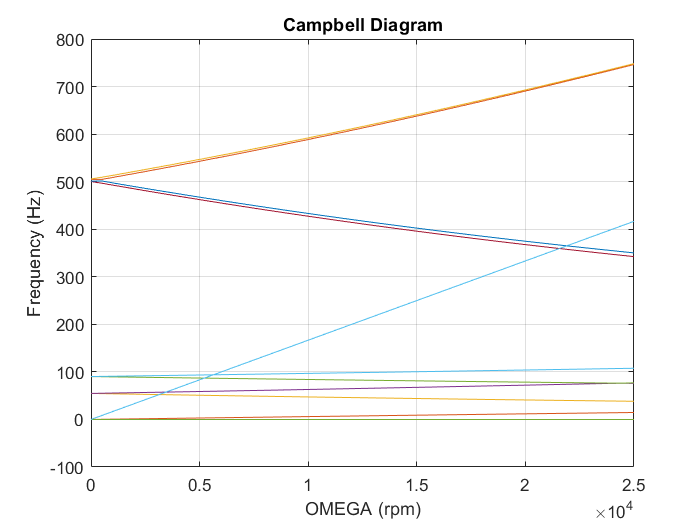

clear w
for omega= 0:500:25000   % in RPM
    S_new = subs(S,'omega',omega);
    landa = vpa(S_new);
    w(:,round(omega/500) + 1) = imag(1./landa);
    F = w./(2*pi);
end
% [eigvector, eigvalue]=eig(A - (lan).*B)
omega= 0:500:25000;
plot(omega,F(1:n*4,:))        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
grid on
hold on 
plot(omega,omega/60)
title('Campbell Diagram')
xlabel('OMEGA (rpm)')
ylabel('Frequency (Hz)')